Homework #07

## 1

s1='takeasadsong'; s2='makeitbetter';
x=[6,-4,-2]; y=[53,-42,-13];


1a)

[1a pic]

1b)

[1b pic]

1c) A set of points where the distance from origin (radius) is the same.

[1c pic]

## 2

2a)

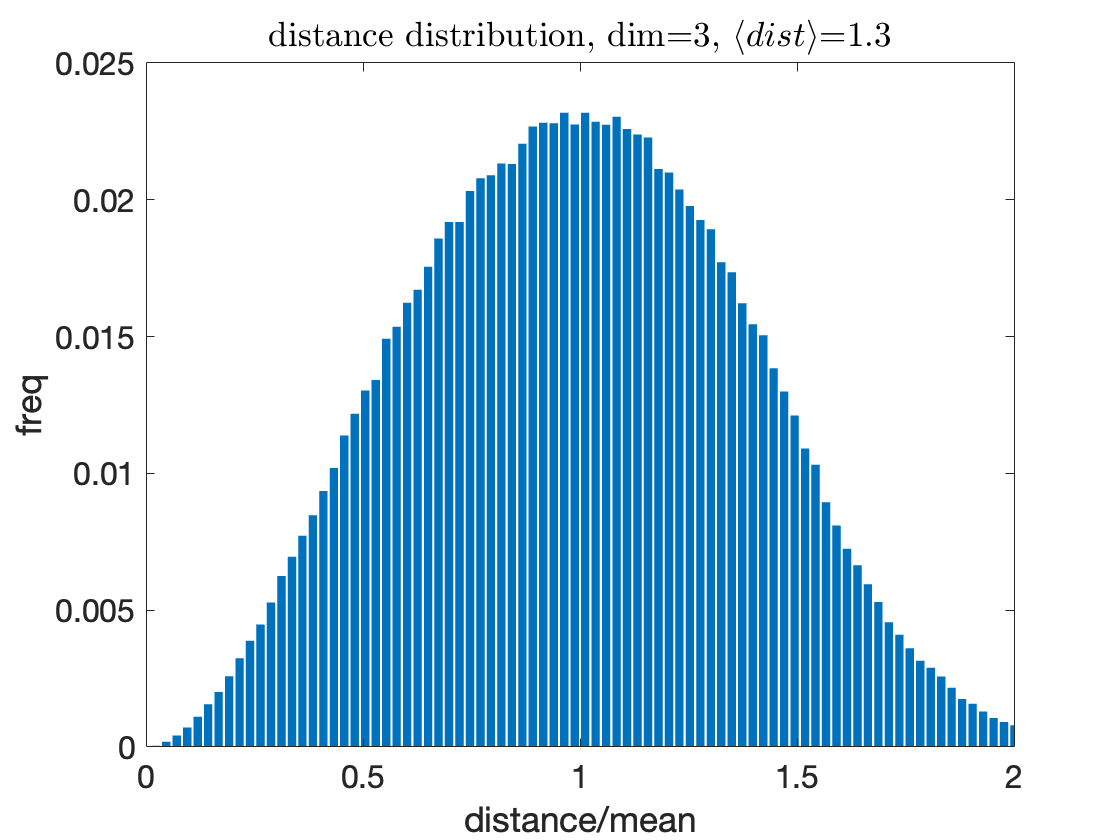

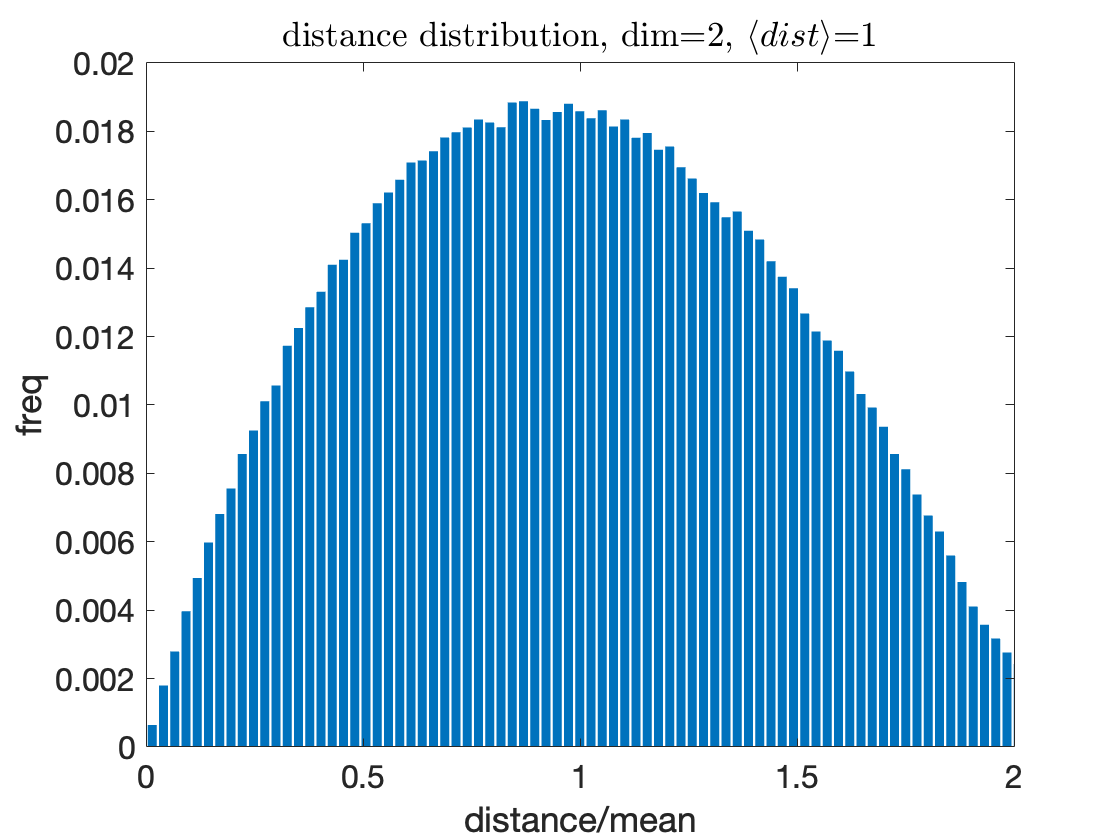

% parameters:
N=1000; % number of vectors, make it even
% font size:
set(0,'defaulttextfontsize',16); set(0,'defaultaxesfontsize',16);

% loop over dimension:
for d=[3,2]
  % setup a set of row vectors of uniformly distributed random
  % numbers between -1 and 1 - each row of X is a vector:
  X=2*(rand(N,d)-0.5);
  Xnorm=zeros(N,1);
  for i=1:N
    Xnorm(i)=sqrt(sum(X(i,:).*X(i,:)));
  end
  
  i=0;
  distances=NaN(N*(N-1)/2,1);
  angles=NaN(N*(N-1)/2,1);
  for n=1:N
    for m=2:(n-1)
      i=i+1;
      diff=X(n,:)-X(m,:); distances(i)=sqrt(sum(diff.*diff));
      angles(i)=acos(sum(X(n,:).*X(m,:))/(Xnorm(n)*Xnorm(m)));
    end
  end
  dist_mean=mean(distances(1:i));
  distances=distances(1:i)/dist_mean;
  angle_mean=mean(angles(1:i))*180/pi;
  angles=angles(1:i)*180/pi;

  figure; clf
  % plot distribution of distances:
  [counts,centers]=hist(distances,100);
  counts=counts/sum(counts);
  bar(centers,counts,'edgecolor','none');
  xlim([0,2]);
  title(sprintf('distance distribution, dim=%d, $\\langle{}dist\\rangle$=%.2g',d,dist_mean) ...
        ,'interpreter','LaTeX');
  xlabel('distance/mean');
  ylabel('freq');
  
end

L3 distances are increasingly centered around the average of random squared distances (for all the dims), which is 1 in these random vectors, compared to L2 because as the dim increases, these random value differences will go towards this average, so the distribution will close in on this average.

2b) Because with L1, each dimension will add distance to the total distance, so with increasing n dims, there will be increasing n terms for the total L1 distance.

2c) So since the formula for the angle (cosine dist) is the arccos of the correlation between points, as dim increases, then the points will become less and less correlated and it will go towards the arccos of 0, or center around 90 degrees. 

## 3

X=[  5, 4.5, 6, 9, 9.5, 4, 2, 2.5, 5;...
    9.5, 5,  9, 6, 4.5, 4, 5,  3,  8];

3a) **smallest increase in cluster variance:**

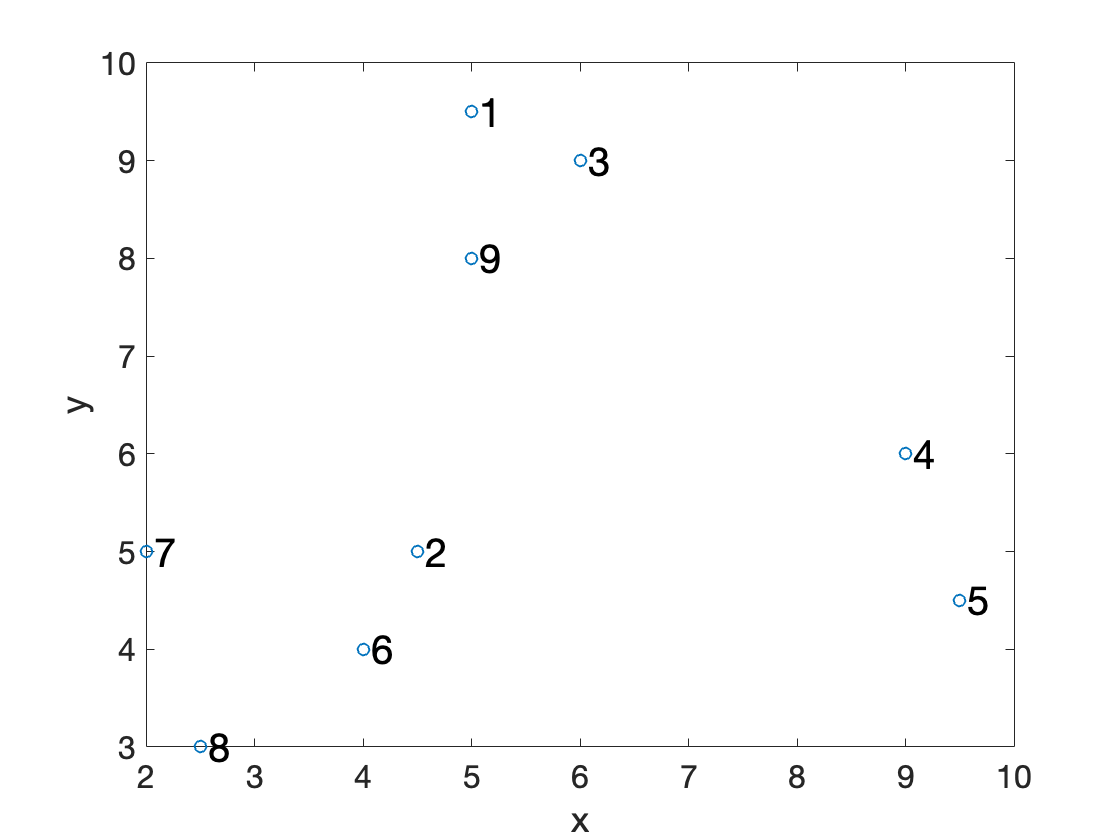

figure;clf; scatter(X(1,:),X(2,:));
box on; hold on;xlabel('x');ylabel('y');
for ii=1:length(X(1,:))
text(X(1,ii)+0.07,X(2,ii),num2str(ii)...
    ,'FontSize',20);end

[3a pic]

TF said only need to hand draw dendrogram for the first two mergings.

[3a_dendrogram pic]

Rest of the clusters and dendrogram:

Xnew = horzcat(X, [4.25; 4.5], [5.5; 9.25]);
X_num = horzcat(ones(1, 9), 2, 2);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750
   14.6250    3.1250   16.0000   25.0000   28.2500    2.5000         0    2.1250    9.0000    3.5417   20.2083
   24.2500    4.0000   24.1250   25.6250   25.6250    1.6250    2.1250         0   15.6250    3.5417   32.0417
    1.1250    4.6250    1.0000   10.0000   16.2500    8.5000    9.0000   15.6250         0    8.5417

Second smallest variance increase is between 9 and centroid of (1,3)

xc=(1/3)*sum(Xnew(:,9)+Xnew(:,1)+Xnew(:,3),2)

xc =     5.3333
    8.8333


Xnew = horzcat(Xnew, xc);
X_num = horzcat(X_num, 3);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083    0.4167
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083   11.5417
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083    0.3542
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083   16.1042
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083   27.1042
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750   18.8542
   14.6250    3.1250   16.0000   25.0000   28.2500    2.5000         0    2.1250    9.0000    3.5417   20.2083   19.3542
   24.2500    4.0000   24.1250   25.6250   25.6250    1.6250    2.1250         0   15.6250    3.5417   32.0417   31.5417
    1.1250    4.6250

Next smallest is 4 and 5

xc=(1/2)*sum(Xnew(:,4)+Xnew(:,5),2)

xc =     9.2500
    5.2500


Xnew = horzcat(Xnew, xc);
X_num = horzcat(X_num, 2);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083    0.4167   24.0833
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083   11.5417   15.0833
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083    0.3542   16.4167
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083   16.1042    0.4167
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083   27.1042    0.4167
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750   18.8542   19.4167
   14.6250    3.1250   16.0000   25.0000   28.2500    2.5000         0    2.1250    9.0000    3.5417   20.2083   19.3542   35.0833
   24.2500    4.0000   24.1250   25.6250   25.6250    1.6250    2.1250 

Next smallest is 7 and 8

xc=(1/2)*sum(Xnew(:,7)+Xnew(:,8),2)

xc =     2.2500
    4.0000


Xnew = horzcat(Xnew, xc);
X_num = horzcat(X_num, 2);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083    0.4167   24.0833   25.2083
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083   11.5417   15.0833    4.0417
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083    0.3542   16.4167   26.0417
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083   16.1042    0.4167   33.0417
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083   27.1042    0.4167   35.2083
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750   18.8542   19.4167    2.0417
   14.6250    3.1250   16.0000   25.0000   28.2500    2.5000         0    2.1250    9.0000    3.5417   20.2083   19.3542   35.0833    0.7083
 

Next smallest is between (2,6) (10 in my continuously updated Xnew matrix) and (7,8) (14 in Xnew)

xc=(1/4)*sum(Xnew(:,2)+Xnew(:,6)+Xnew(:,7)+Xnew(:,8),2)

xc =     3.2500
    4.2500


Xnew = horzcat(Xnew, xc);
X_num = horzcat(X_num, 4);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083    0.4167   24.0833   25.2083   24.5000
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083   11.5417   15.0833    4.0417    1.7000
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083    0.3542   16.4167   26.0417   24.1000
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083   16.1042    0.4167   33.0417   28.9000
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083   27.1042    0.4167   35.2083   31.3000
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750   18.8542   19.4167    2.0417    0.5000
   14.6250    3.1250   16.0000   25.0000   28.2500    2.5000         0    2.1250  

Finally, (1, 3, 9) (12 in Xnew) and (4,5) (13 in Xnew).

xc=(1/5)*sum(Xnew(:,1)+Xnew(:,3)+Xnew(:,9)+Xnew(:,4)+Xnew(:,5),2)

xc =     6.9000
    7.4000


Xnew = horzcat(Xnew, xc);
X_num = horzcat(X_num, 5);

[M,N] = size(Xnew);
var_delta=[];
for a=1:1:N
    for b=1:1:N
        Na=X_num(:,a);
        Nb=X_num(:,b);
        xa=Xnew(:, a);
        xb=Xnew(:,b);
        var_delta(a, b) = (Na*Nb/(Na+Nb)) * (((xb-xa)'*(xb-xa)));
    end
end
var_delta

var_delta =          0   10.2500    0.6250   14.1250   22.6250   15.6250   14.6250   24.2500    1.1250   17.0417    0.2083    0.4167   24.0833   25.2083   24.5000    6.6833
   10.2500         0    9.1250   10.6250   12.6250    0.6250    3.1250    4.0000    4.6250    0.2083   12.7083   11.5417   15.0833    4.0417    1.7000    9.6000
    0.6250    9.1250         0    9.0000   16.2500   14.5000   16.0000   24.1250    1.0000   15.5417    0.2083    0.3542   16.4167   26.0417   24.1000    2.8083
   14.1250   10.6250    9.0000         0    1.2500   14.5000   25.0000   25.6250   10.0000   16.5417   15.2083   16.1042    0.4167   33.0417   28.9000    5.3083
   22.6250   12.6250   16.2500    1.2500         0   15.2500   28.2500   25.6250   16.2500   18.3750   25.7083   27.1042    0.4167   35.2083   31.3000   12.6417
   15.6250    0.6250   14.5000   14.5000   15.2500         0    2.5000    1.6250    8.5000    0.2083   19.8750   18.8542   19.4167    2.0417    0.5000   16.6417
   14.6250    3.1250  

In summary,

preZ=[2	6;
1	3;
9	11;
4	5;
7	8;
10	14;
12	13;
15	16]

preZ =      2     6
     1     3
     9    11
     4     5
     7     8
    10    14
    12    13
    15    16


Finding the dendrogram y-axis,

% matlab version bc looks better on dendrogram
Z_vars = [ sqrt(2*var_delta(2,6));
    sqrt(2*var_delta(1,3));
    sqrt(2*var_delta(11,9));
    sqrt(2*var_delta(4,5));
    sqrt(2*var_delta(7,8));
    sqrt(2*var_delta(10,14));
    sqrt(2*var_delta(12,13));
    sqrt(2*var_delta(15,16));
    ]

Z_vars =     1.1180
    1.1180
    1.5546
    1.5811
    2.0616
    2.9155
    8.2239
   10.1642


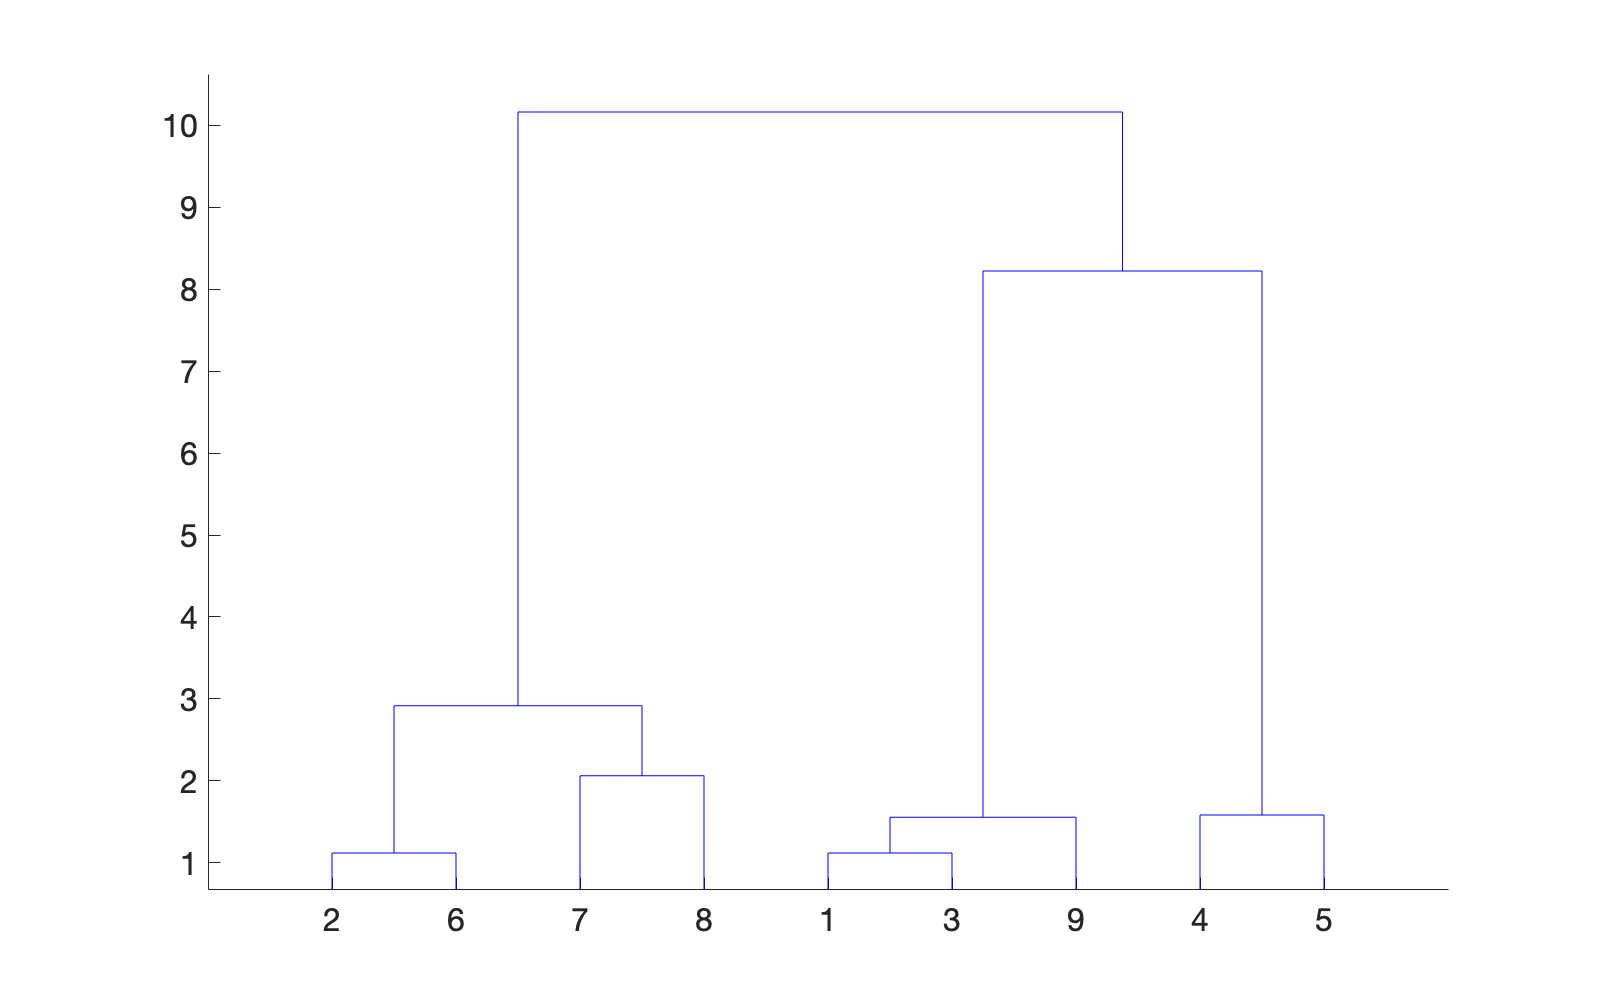

dendro=horzcat(preZ, Z_vars);
dendrogram(dendro);

The vertical distances in the dendrogram represents how far along and the variance at merging for each instance of two cluster merging.

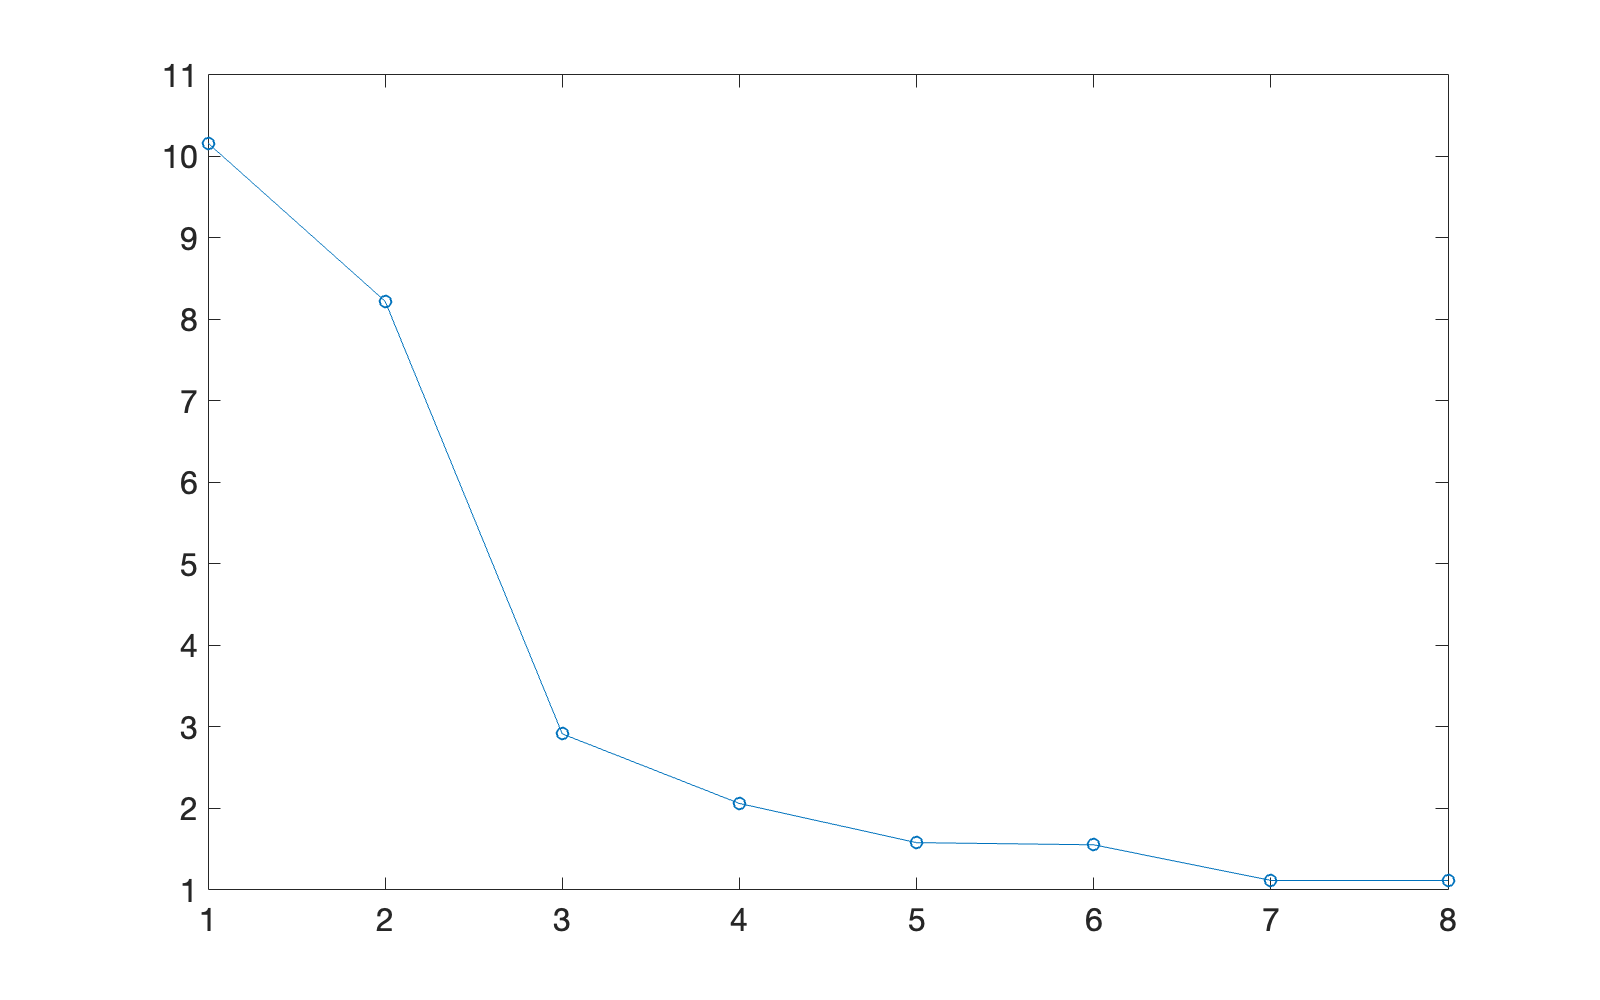

plot(1:1:8, flip(Z_vars'), '-o');

Ideally we want to find where the changes in variances start to increase way more as the clustering continues. From the elbow plot that looks like at around 3 clusters.

3b)

% Y is the Euclid distances of X
Y=pdist(X');
% convert to set of pairwise distance vectors
% so distances(i, j) is the dist between points i and j
distances=squareform(Y)

distances =          0    4.5277    1.1180    5.3151    6.7268    5.5902    5.4083    6.9642    1.5000
    4.5277         0    4.2720    4.6098    5.0249    1.1180    2.5000    2.8284    3.0414
    1.1180    4.2720         0    4.2426    5.7009    5.3852    5.6569    6.9462    1.4142
    5.3151    4.6098    4.2426         0    1.5811    5.3852    7.0711    7.1589    4.4721
    6.7268    5.0249    5.7009    1.5811         0    5.5227    7.5166    7.1589    5.7009
    5.5902    1.1180    5.3852    5.3852    5.5227         0    2.2361    1.8028    4.1231
    5.4083    2.5000    5.6569    7.0711    7.5166    2.2361         0    2.0616    4.2426
    6.9642    2.8284    6.9462    7.1589    7.1589    1.8028    2.0616         0    5.5902
    1.5000    3.0414    1.4142    4.4721    5.7009    4.1231    4.2426    5.5902         0


% cluster by the cluster variance method ("Ward method")
Z=linkage(Y,'ward');
% plot dendrogram from Z
dendrogram(Z);

% set k to 3
k=3;
% idx is the cluster assignment for each point 
% using 3 clusters
idx=cluster(Z,'maxclust',k)'

idx =      1     3     1     2     2     3     3     3     1


3c)

distances

distances =          0    4.5277    1.1180    5.3151    6.7268    5.5902    5.4083    6.9642    1.5000
    4.5277         0    4.2720    4.6098    5.0249    1.1180    2.5000    2.8284    3.0414
    1.1180    4.2720         0    4.2426    5.7009    5.3852    5.6569    6.9462    1.4142
    5.3151    4.6098    4.2426         0    1.5811    5.3852    7.0711    7.1589    4.4721
    6.7268    5.0249    5.7009    1.5811         0    5.5227    7.5166    7.1589    5.7009
    5.5902    1.1180    5.3852    5.3852    5.5227         0    2.2361    1.8028    4.1231
    5.4083    2.5000    5.6569    7.0711    7.5166    2.2361         0    2.0616    4.2426
    6.9642    2.8284    6.9462    7.1589    7.1589    1.8028    2.0616         0    5.5902
    1.5000    3.0414    1.4142    4.4721    5.7009    4.1231    4.2426    5.5902         0


distances is a matrix of pairwise distance vectors between every point and every other point. So distances(i, j) is the dist between points i and j and the diagonal, distances between the same point and itself, is always 0.

Z

Z =     2.0000    6.0000    1.1180
    1.0000    3.0000    1.1180
    9.0000   11.0000    1.5546
    4.0000    5.0000    1.5811
    7.0000    8.0000    2.0616
   10.0000   14.0000    2.9155
   12.0000   13.0000    8.2239
   15.0000   16.0000   10.1642


Z is the output matrix from the clustering method where each row is a newly formed cluster going down. The two clusters that were merged to create each newly formed cluster are the indices in the first two columns and the third column is the y axes for how far along before this cluster was formed. Each newly formed cluster then also gets a new index past the original number of datapoints (so past 9).

idx

idx =      1     3     1     2     2     3     3     3     1


This is the final cluster assignments for all the points. Each column has that respective datapoint's cluster assignment based on using k input number of clusters.

dendrogram(Z)

This function plots the dendrogram based on the cluster formation information from Z.

The results from Matlab's clustering analysis are the same as mine.

## 4

4a) TF said only need to find the initial clusteroids for each k

X=[ 5, 4.5, 6, 9, 9.5, 4, 2, 2.5, 5;
9.5, 5, 9, 6, 4.5, 4, 5, 3, 8];

ks=[2 3 4];

Y=pdist(X');
distances=squareform(Y)

distances =          0    4.5277    1.1180    5.3151    6.7268    5.5902    5.4083    6.9642    1.5000
    4.5277         0    4.2720    4.6098    5.0249    1.1180    2.5000    2.8284    3.0414
    1.1180    4.2720         0    4.2426    5.7009    5.3852    5.6569    6.9462    1.4142
    5.3151    4.6098    4.2426         0    1.5811    5.3852    7.0711    7.1589    4.4721
    6.7268    5.0249    5.7009    1.5811         0    5.5227    7.5166    7.1589    5.7009
    5.5902    1.1180    5.3852    5.3852    5.5227         0    2.2361    1.8028    4.1231
    5.4083    2.5000    5.6569    7.0711    7.5166    2.2361         0    2.0616    4.2426
    6.9642    2.8284    6.9462    7.1589    7.1589    1.8028    2.0616         0    5.5902
    1.5000    3.0414    1.4142    4.4721    5.7009    4.1231    4.2426    5.5902         0


k=2: So the farthest pt from 4 is 8, so that's the second initial clusteroid pt. Then points that are closer to 4 will go to that clusteroid so (1, 3, 5, 9) and points closer to 8 will go to that clusteroid so (2, 6, 7).

idx = [1 2 1 1 1 2 2 2 1]

k=3: The pt with the greatest smallest dist out of distances to 4 and 8 is 1. So (5) is closest to and joins clusteroid 4, (2, 6, 7) for clusteroid 8, and (3, 9) for clusteroid 1.

idx = [1 3 1 2 2 3 3 3 1]

k=4: The pt with the greatest smallest dist out of distances to 4, 8, and 1 is 2. (5) for clusteroid 4, (7) for clusteroid 8, (3, 9) for clusteroid 1, (6) for clusteroid 2.

idx = [1 2 1 3 3 2 4 4 1]

4b)

[Cluster the above data using a handcalculation using k-means for k = 3]

4c) 

ks=[2 3 4 5];

for i = 1:1:length(ks)
    k = ks(1,i);
    
    opts = statset('Display','final');
    [idx,C] = kmeans(X',k, ...
    'Distance','sqeuclidean' ...
    ,'Replicates',5,'Options',opts);
    disp(['idx for k=' num2str(k) ' :']);disp(idx)
end

Replicate 1, 1 iterations, total sum of distances = 43.9.
Replicate 2, 1 iterations, total sum of distances = 53.5357.
Replicate 3, 2 iterations, total sum of distances = 43.9.
Replicate 4, 2 iterations, total sum of distances = 53.5357.
Replicate 5, 1 iterations, total sum of distances = 43.9.
Best total sum of distances = 43.9


idx for k=2 :
     1
     2
     1
     1
     1
     2
     2
     2
     1



Replicate 1, 1 iterations, total sum of distances = 10.0833.
Replicate 2, 1 iterations, total sum of distances = 10.0833.
Replicate 3, 2 iterations, total sum of distances = 10.0833.
Replicate 4, 2 iterations, total sum of distances = 10.0833.
Replicate 5, 3 iterations, total sum of distances = 10.0833.
Best total sum of distances = 10.0833


idx for k=3 :
     1
     3
     1
     2
     2
     3
     3
     3
     1



Replicate 1, 1 iterations, total sum of distances = 8.83333.
Replicate 2, 1 iterations, total sum of distances = 5.83333.
Replicate 3, 1 iterations, total sum of distances = 8.875.
Replicate 4, 1 iterations, total sum of distances = 5.83333.
Replicate 5, 1 iterations, total sum of distances = 5.83333.
Best total sum of distances = 5.83333


idx for k=4 :
     1
     4
     1
     3
     3
     4
     2
     2
     1



Replicate 1, 1 iterations, total sum of distances = 4.625.
Replicate 2, 1 iterations, total sum of distances = 4.625.
Replicate 3, 1 iterations, total sum of distances = 3.70833.
Replicate 4, 1 iterations, total sum of distances = 7.625.
Replicate 5, 1 iterations, total sum of distances = 3.70833.
Best total sum of distances = 3.70833


idx for k=5 :
     3
     1
     3
     2
     2
     1
     4
     5
     3



4d)

for i = 1:1:length(ks)
    k = ks(1,i);
    
    opts = statset('Display','final');
    [idx,C] = kmeans(X',k, ...
    'Distance','sqeuclidean' ...
    ,'Replicates',5,'Options',opts);

    for j=1:1:k
        pts = find(idx==j);
        xc = (1/length(pts)) * sum(X(:,pts),2);
        radius(i,j) = max(sum((X(:,pts) - xc).^2));
        
        % also go ahead and find diameters
        if length(pts) < 2
            diameter(i,j) = 0;
        else
            diameter_mat = pdist(X(:, pts)');
            diameter(i,j) = max(diameter_mat(:));
        end
        disp(['diameter for k=' num2str(k) ' cluster ' num2str(j) ':'])
        disp(diameter(i,j))
    end
end

Replicate 1, 1 iterations, total sum of distances = 43.9.
Replicate 2, 2 iterations, total sum of distances = 53.5357.
Replicate 3, 1 iterations, total sum of distances = 43.9.
Replicate 4, 1 iterations, total sum of distances = 43.9.
Replicate 5, 1 iterations, total sum of distances = 43.9.
Best total sum of distances = 43.9


diameter for k=2 cluster 1:


    6.7268



diameter for k=2 cluster 2:


    2.8284



Replicate 1, 1 iterations, total sum of distances = 10.0833.
Replicate 2, 1 iterations, total sum of distances = 10.0833.
Replicate 3, 1 iterations, total sum of distances = 10.0833.
Replicate 4, 4 iterations, total sum of distances = 10.0833.
Replicate 5, 1 iterations, total sum of distances = 10.0833.
Best total sum of distances = 10.0833


diameter for k=3 cluster 1:


    1.5000



diameter for k=3 cluster 2:


    2.8284



diameter for k=3 cluster 3:


    1.5811



Replicate 1, 1 iterations, total sum of distances = 5.83333.
Replicate 2, 1 iterations, total sum of distances = 5.83333.
Replicate 3, 1 iterations, total sum of distances = 8.875.
Replicate 4, 1 iterations, total sum of distances = 5.83333.
Replicate 5, 1 iterations, total sum of distances = 7.83333.
Best total sum of distances = 5.83333


diameter for k=4 cluster 1:


    1.1180



diameter for k=4 cluster 2:


    2.0616



diameter for k=4 cluster 3:


    1.5000



diameter for k=4 cluster 4:


    1.5811



Replicate 1, 1 iterations, total sum of distances = 4.58333.
Replicate 2, 1 iterations, total sum of distances = 7.
Replicate 3, 1 iterations, total sum of distances = 6.04167.
Replicate 4, 1 iterations, total sum of distances = 3.70833.
Replicate 5, 1 iterations, total sum of distances = 4.625.
Best total sum of distances = 3.70833


diameter for k=5 cluster 1:


    1.5000



diameter for k=5 cluster 2:


    1.5811



diameter for k=5 cluster 3:


     0



diameter for k=5 cluster 4:


    1.1180



diameter for k=5 cluster 5:


     0



So we want to minimize the max cluster radius,

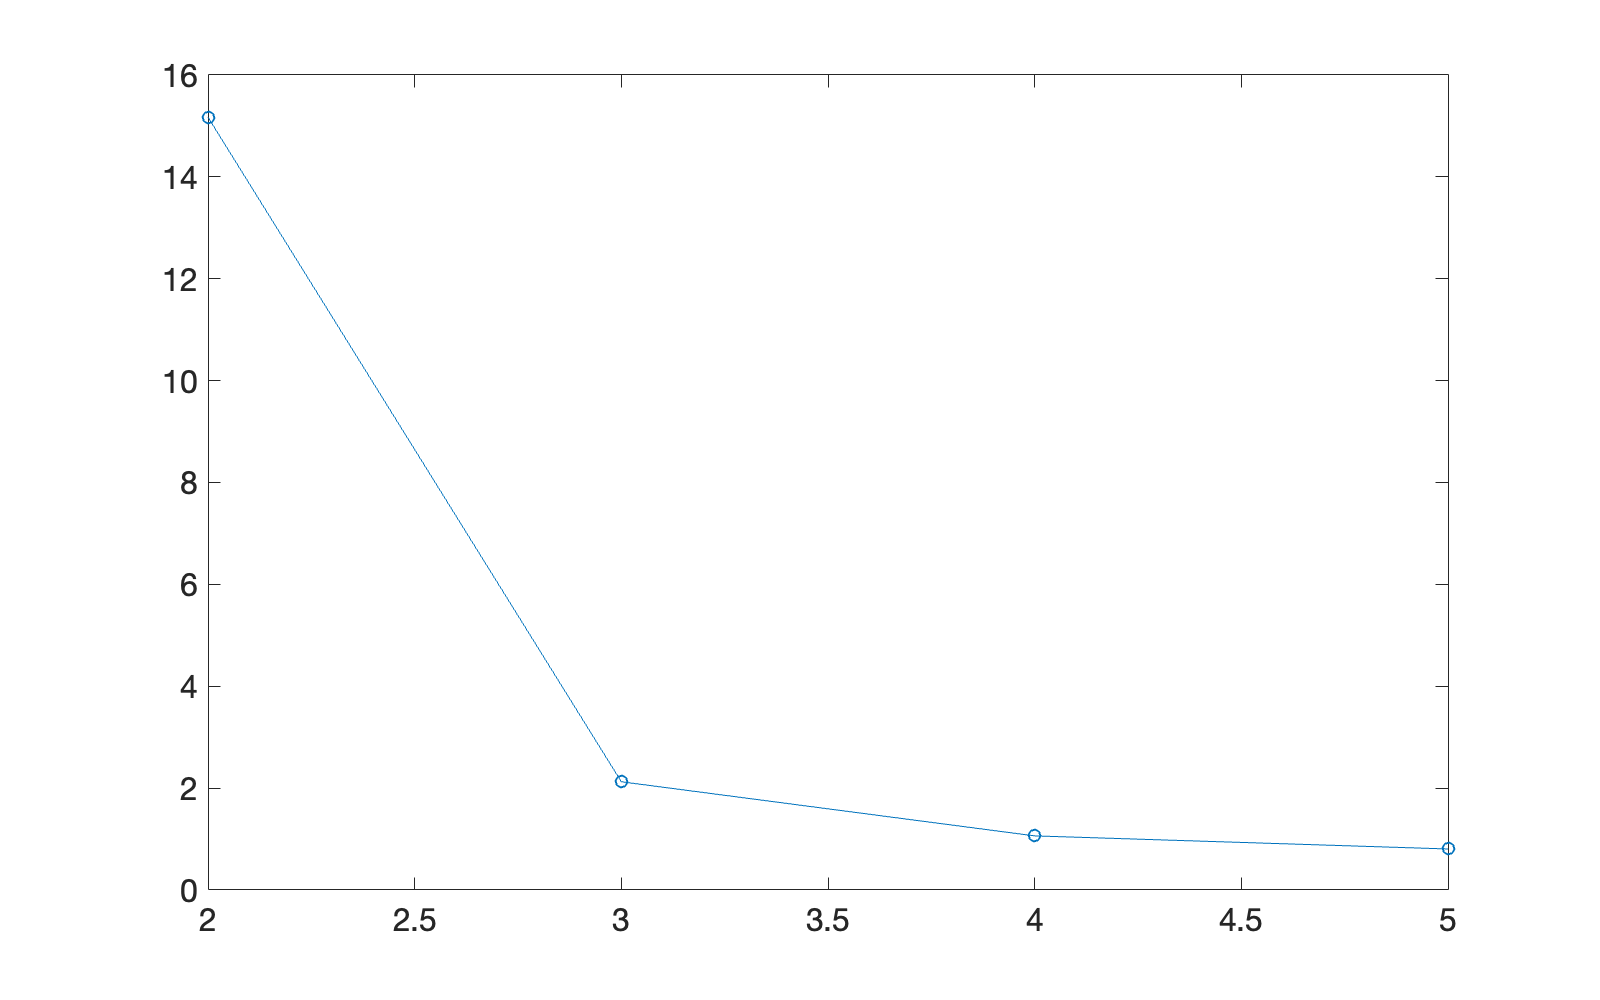

plot(ks,max(radius, [], 2)', '-o')

Ideally we want to find where the changes in max radius start to increase way more as k clustering continues. From the elbow plot that looks like at around 3 clusters.

4e)

In this case, they both gave the same clusters with the same datapoints. Our data does not spatially have any clusters that are more densely clustered than others or can equally give a minimum radius by splitting a cluster or something like that, so hierarchal clustering and making clusters one by one via variance increases and k-means clustering by slowly finding 3 spatially distant centroids and clusters of small-ish radius will give a similar result.